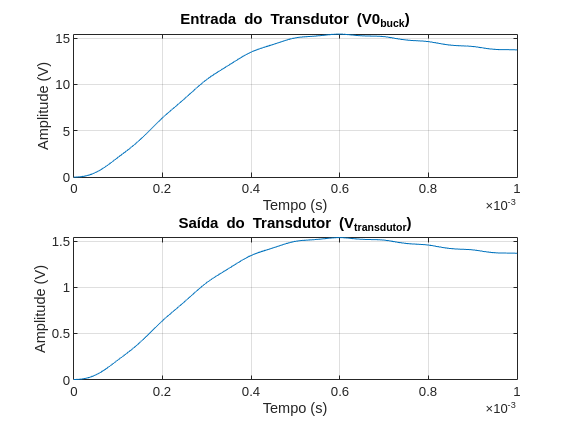

Saída do transdutor salva em V_transdutor.mat


%% Analise_Transdutor.m

% Carrega V0_buck.mat, aplica o transdutor e salva V_transdutor.mat

% Carregar dados do Buck
load('V0_buck.mat', 'V0_buck', 't', 'Fs');

% Parâmetros do transdutor (divisor de tensão)
R1 = 9e3; R2 = 1e3;
G_transdutor = R2 / (R1 + R2); % Ganho = 0.5

% Aplicar transdutor
V_transdutor = V0_buck * G_transdutor;

% Salvar saída
save('V_transdutor.mat', 'V_transdutor', 't', 'Fs');
disp('Saída do transdutor salva em dados/V_transdutor.mat');

% Plotar resultados
figure;
subplot(2,1,1); plot(t, V0_buck); 
%ylim([0]);
title('Entrada do Transdutor (V0_{buck})');
subplot(2,1,2); plot(t, V_transdutor); title('Saída do Transdutor (V_{transdutor})');

% Salvar saída
save('V_transdutor.mat', 'V_transdutor', 't', 'Fs');
disp('Saída do transdutor salva em dados/V_transdutor.mat');